## Introduction

This work provides a complete dataset containing surface electromyography (sEMG) signals acquired from the uppe-limb with FloatEVO exoskeleton at **sampling frequency of 2000 Hz. **

Bipolar EMG is a surface EMG (sEMG) technique that measures the difference in voltage between two electrodes on one muscle. 

Often, the **SENIAM guidelines** are followed and the **electrodes** are placed at a **2 cm distance from one another**. (https://knowledge.tmsi.com/what-is-the-difference-between-hd-emg-and-bipolar-emg)

The dataset recorded the data of **4 participants** between 24 and 37 years old without neuromuscular diseases or cardiovascular problems. 

The test protocol consisted of sEMG signals acquisition corresponding to h**orizontal abductions** at different planes 30°, 60°, 90°, and 120° wearing FloatEVO upper-limb exoskeleton considering three repetitions for each exercise.

Also, the dataset contains general information such as anthropometric measures of the upper limb, gender, age, laterally of the person, and physical condition. 

Likewise, the implemented acquisition system consists of a 16 sEMG channels placed on the reference muclses.

The database could be used for the evaluation of the evolution of patients in rehabilitation processes, control of upper limb exoskeleton, and biomechanical analysis.

## Purpose

The purpose of this experiment is to analyse muscle activations while performing horizontal abductions at different planes 30°, 60°, 90°, and 120° wearing FloatEVO upper-limb exoskeleton, relying on sEMG signals recorded with Cometa Wave Plus EMG system.

There are different goals in this analysis:

- Time-frequency analysis and fatigue

- Verify the presence of coactivation activity between bicep and tricep during the exercise

- Investigate asynchronous behaviour  between counterpart muscles

- Evaluate the muscles actvity during the aforementioned exercises.

## Experimental Protocol

- **Movement measured**

The subject keeps the hands palms down under the shoulders, the toes tips of the feet on the ground, and the back straight, pushing the body up and down by an alternate straightening and bending of the arms. 

- **Repetitions and durations**

The recording lasts about 35 seconds while the subject performs 30 repetitions of the same movement.

- **Muscles of interest**

Multiple muscles are active during the exercise, but the analysis is focused on the most revelant:

- **Positioning of SENIAM sensors:**

Sensors must be placed on clean and dry surfaces in order to have a good electrode-skin contact, necessary to obtain better sEMG-recording in terms of amplitude with fewer and small artefacts and with a noise reduction. 

Every sensor has two bipolar elecrodes on the same muscle, one for reference and one for recording.

- Biceps electrodes need to be placed on the line between the medial acromion and the fossa cubit at 1/3 from the fossa cubit. The orientation follows the direction of the line between the acromion and the fossa cubit. 

- Triceps electrodes need to be placed at 50 % on the line between the posterior crista of the acromion and the olecranon at 2 finger widths medial to the line. The orientation follows the direction of the line between the posterior crista of the acromion and the olecranon.

- Pectoralis electrodes need to be placed on the line between the crest of greater tubercle of humerus (insertion) and the anterior surface of sternum (origin) in its upper part.                      

d) **Findings expectations**

- Cyclic muscle activations: due to the repetitions of the same movement patterns, stereotypical EMG trends are expected.

- Fatigue over time: because of the muscles work load while performing the task, some evidence of fatigue should be seen. 

- Lower activations of biceps: since biceps are mainly involved in pulling efforts, the push-up exercise mostly activates their antagonist muscles, i.e. triceps.

- Interferences due to heartbeat: due to the proximity of the left pectoralis electrodes and the heart, the sensors may register cardiac activity as well. 

clear all;
close all;
clc;

opengl('software');

warning('off')

% Horizontal abduction trajectory angles
angles = [30, 60, 90];

% Assistance and Resistance levels
conditions = {'AssBassa', 'AssMedia', 'Cinematica', 'Eval', ...
              'ResBassa', 'ResAlta', 'ResMedia', ...
              'ResBassaGauss', 'ResMediaGauss', 'ResAltaGauss', ...
              'senzaESO'};

% Mapping from Italian condition names to English equivalents
conditionsEng = {'Low Assistance', 'Medium Assistance', 'Passive Kinematics', 'Transparency', ...
                 'Low Resistance', 'High Resistance', 'Medium Resistance', ...
                 'Low Gaussian Resistance', 'Medium Gaussian Resistance', 'High Gaussian Resistance', ...
                 'Without Exo'};

% Muscles engaged in EMG analysis
nameMuscles = {'R.Ant.Deltoid', 'R.Mid.Deltoid', 'R.Post. Deltoid', 'R.Pect. Major', ...
               'R.Upper Trap.', 'R.Middle Trap.', 'R.Lower Trap.', 'R.Biceps Br.', ...
               'R.Med. Triceps', 'R.Lat. Triceps', 'R.Lat.Dorsi', 'R. Serratus Ant.', ...
               'R.Brachiorad', 'R.Flex.Carp.R', 'R.Ext.Carp.Rad.', 'R. Biceps Brevis Br.'};

numMuscles = length(nameMuscles);

## **Data reading and storage**

- **Read c3d file**

% datadir = fullfile('C:\Users\mursi\OneDrive - Fondazione Istituto Italiano Tecnologia\ThesisRehabErzelli\Matlab\RoboticsMU', 'S1_C3D');
datadir = fullfile('C:\Users\User\Desktop\CODICI TESI\sEMG', 'S1_C3D');

% Structure initialization for storing all C3D data
allData = struct();

% Cycle for all the assistance/resistance conditions
for c = 1:length(conditions)
    condition = conditions{c};
    
    % Cycle for all the trajectory angles
    for a = 1:length(angles)
        angle = angles(a);
        
        % Creation of the file name
        fname = sprintf('%s_%d.c3d', condition, angle);
        
        % Read the .c3d file
        data = readc3d(fullfile(datadir, fname));
        
        % Parameters extraction
        fs = data.Parameter.ANALOG.RATE.data; 
        % nbits = data.Parameter.ANALOG.BITS.data;
        % gain = data.Parameter.ANALOG.GAIN.data;
        % unit = data.Parameter.ANALOG.UNITS.data'; 
        
        % Store the data in the structure allData
        % The structure is indexed for condition and angle
        allData.(condition).(sprintf('Angle_%d', angle)) = struct('data', data, ...
                                                                  'fs', fs);
    end
end
% Now, you can access to data for a certain condition and angle using:
% allData.<condition>.Angle_<angle>.data, ad esempio: allData.AssBassa.Angle_30.data

- **Read txt file**

% datadir = fullfile('C:\Users\mursi\OneDrive - Fondazione Istituto Italiano Tecnologia\ThesisRehabErzelli\Matlab\RoboticsMU', 'S1_ASCII');
datadir = fullfile('C:\Users\User\Desktop\CODICI TESI\sEMG', 'S1_ASCII');

% Structure initialization for storing all TXT data
allTxtData = struct();

% Cycle for all conditions
for c = 1:length(conditions)
    condition = conditions{c};
    
    % Cycle for all angles
    for a = 1:length(angles)
        angle = angles(a);
        
        % Creation of the file .txt name
        fname = sprintf('%s_%d.txt', condition, angle);
        filepath = fullfile(datadir, fname);

        % Apri il file
        fileID = fopen(filepath, 'r');     
        
        % Salta le prime quattro righe
        for i = 1:4
            fgetl(fileID);
        end

        % Leggi il resto del file in una tabella
        data = readtable(filepath);

        % Chiudi il file
        fclose(fileID);

        % Remove the 1st column that is the time
        data = data(:, 2:17);

        % Imposta i nomi delle variabili con i nomi dei muscoli
        data.Properties.VariableNames = nameMuscles;

        % Numero di campioni e tempo
        nsamples = height(data); % Usa height invece di length per le tabelle
        time = (0:(nsamples-1)) / fs;

        % Memorizzazione dei dati nella struttura allTxtData
        allTxtData.(condition).(sprintf('Angle_%d', angle)) = struct('data', data, ...
            'nsamples', nsamples, ...
            'time', time, ...
            'fs', fs);
    end
end
% Now, you can access to data for a certain condition and angle using:
% allTxtData.<condition>.Angle_<angle>.data, ad esempio: allTxtData.AssBassa.Angle_30.data

- **Read MVC data**

% Initialize a row vector for storing MVC values
mvc = zeros(1, numMuscles);

% Load MVC data for each muscle
for i = 1:numMuscles
    fname = sprintf('MVC_E%d.txt', i);
    filepath = fullfile(datadir, fname);

    % Apri il file
    fileID = fopen(filepath, 'r');

    % Salta le prime quattro righe
    for j = 1:4
        fgetl(fileID);
    end

    % Leggi il resto del file in una tabella
    data = readtable(filepath);

    % Chiudi il file
    fclose(fileID);

    % Remove the 1st column that is the time
    data = data(:, 2:17);

    % Imposta i nomi delle variabili con i nomi dei muscoli
    data.Properties.VariableNames = nameMuscles;

    % Numero di campioni e tempo
    nsamples = height(data); % Usa height invece di length per le tabelle
    time = (0:(nsamples-1)) / fs; % fc deve essere definito, viene dai file .c3d
    
    % Take the right column (i+1)
    muscleData = data{:, i};
    
    % Take the max of the interested column (uV)
    mvc(i) = max(muscleData);
end

## Row Data Plot

clear fileID filepath fname angle datadir 
figure;

% Iterate through each condition
for c = 1:length(conditions)
    condition = conditions{c};
    conditionEng = conditionsEng{c};

    % Iterate through each angle
    for a = 1:length(angles)
        angle = angles(a);
        
        % Access the raw EMG data for this condition and angle
        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
        
        % Create a new figure for each condition and angle
        figure('Name', sprintf('%s - %d°', conditionEng, angle), 'NumberTitle', 'off');
        
        % Plot each muscle signal in a subplot
        for m = 1:numMuscles
            subplot(4, 4, m);
            plot(time, emgData{:, m}, "Color", "#7E2F8E");
            set(gcf, 'Position', [100, 100, 1600, 900]);

            title(nameMuscles{m}, 'Interpreter', 'none');
            xlabel('Time [s]');
            ylabel('Amplitude [\muV]');
            grid on;

            xticks(0:5:time(end));

            % Imposta FontSize e FontName per tutti gli elementi di testo nei subplot
            all_axes = findall(gcf, 'Type', 'axes');  % Trova tutti gli oggetti 'axes' nella figura corrente

            for ax = all_axes'
                set(findall(ax, '-property', 'FontSize'), 'FontSize', 12, 'FontName', 'Times');
            end
        end
        
        % Add a main title for the entire figure in English
        sgtitle(sprintf('S1 %s - H. Abd. %d° - Raw Signal', conditionEng, angle));
    end
end

## FFT - find the cutoff frequencies of the BP filter

These plots show the frequency range of each signal along with their intensities.

Knowing the sampling frequency fs, by definition the FFT frequencyrange (f_FFT) is the frequnecy resolution from 0 to half the data length 

% freq vector
f_FFT = fs*(0:(nsamples/2))/nsamples;

% Iterate through each condition
for c = 1:length(conditions)
    condition = conditions{c};
    conditionEng = conditionsEng{c};

    % Iterate through each angle
    for a = 1:length(angles)
        angle = angles(a);
        
        % Access the raw EMG data for this condition and angle
        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
        
        % Create a new figure for each condition and angle
        figure('Name', sprintf('%s - %d°', conditionEng, angle), 'NumberTitle', 'off');
        
        % Plot each muscle signal in a subplot
        for m = 1:numMuscles

            % Compute the 2-sided spectrum [-Fmax:+Fmax]
            p1 = fft(emgData{:,m});
            % Normalized FFT (single-sided spectrum)
            p1 = abs(p1/nsamples);
            
            % Compute the single-sided spectrum by taking the positive part
            % of the 2-sided spectrum and multiply by 2
            p1 = p1(1:nsamples/2+1);
            % Double the amplitude of all freq except for the DC component
            % p1(1) and the Nyquist frequency p1(end).
            p1(2:end-1) = 2*p1(2:end-1);
        
            subplot(4,4,m)
            plot(f_FFT,p1);
            set(gcf, 'Position', [100, 100, 1600, 900]);  % Aumenta la dimensione della figura

            title(nameMuscles{m}, 'Interpreter', 'none');        
            xlabel('Frequency [Hz]');
            ylabel('Power [\muV^2]');            
                        
            grid on;
            xticks(0:100:f_FFT(end));
        end

        sgtitle(sprintf('S1 %s - H. Abd. %d° - PSD', conditionEng, angle));
        
    end
end

**Plot Butterworth and Notch filter**

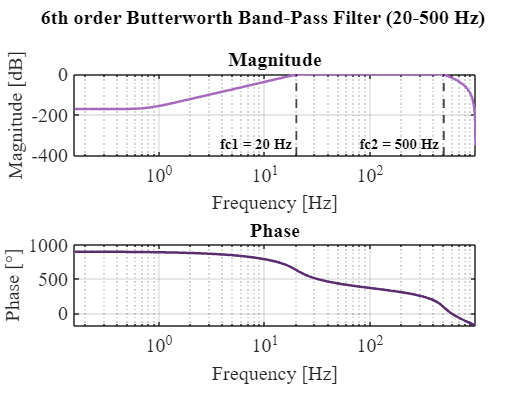

% Parametri dei filtri
PS = PLOT_STANDARDS(); % Assuming PLOT_STANDARDS defines your color scheme.

low_cutoff = 20;   % Frequenza di taglio bassa del filtro passa-banda
high_cutoff = 500; % Frequenza di taglio alta del filtro passa-banda

notch_freq = 50;  % Frequenza del disturbo (es. 50 Hz per il rumore della linea elettrica)
notch_bandwidth = 5;  % Larghezza di banda del filtro Notch (es. 5 Hz)

fs = 2000;

% Creazione del filtro passa-banda Butterworth (ordine 6)
[b_BP, a_BP] = butter(6, [low_cutoff, high_cutoff] / (fs / 2), 'bandpass');

% Creazione del filtro Notch
[d_Notch, c_Notch] = iirnotch(notch_freq / (fs / 2), notch_bandwidth / (fs / 2));

% Convertiamo i coefficienti del filtro in oggetti di sistema per poter usare bode
sys_BP = tf(b_BP, a_BP, 1/fs); % Filtro passa banda Butterworth
sys_Notch = tf(d_Notch, c_Notch, 1/fs); % Filtro Notch

% Plot del Bode per il filtro Butterworth con asse x in Hz
figure('Name', 'Bode Plot - Butterworth Bandpass Filter', 'NumberTitle', 'off');
[mag_BP, phase_BP, wout_BP] = bode(sys_BP);  % Ottenere dati Bode

% Convertire la frequenza da rad/s a Hz
freq_Hz_BP = wout_BP / (2 * pi);

% Imposta la dimensione del font
fontSize = 16;  % Cambia a seconda delle tue necessità
labelFontSize = fontSize - 4; % Dimensione del font per le etichette delle frequenze di cutoff

% Frequenze di cutoff
fc1 = 20;   % Prima frequenza di cutoff
fc2 = 500;  % Seconda frequenza di cutoff

% Primo subplot: Magnitude
subplot(2,1,1);
semilogx(freq_Hz_BP, squeeze(20*log10(mag_BP)), 'Color', PS.DBlue1, 'LineWidth', 2); % Magnitude in dB
title('Magnitude', 'FontSize', fontSize);
xlabel('Frequency [Hz]', 'FontSize', fontSize+2);
ylabel('Magnitude [dB]', 'FontSize', fontSize+2);
xlim([min(freq_Hz_BP) max(freq_Hz_BP)]);
grid on;

% Aggiungi linee verticali tratteggiate per le frequenze di cutoff
hold on;
xline(fc1, '--k', 'LineWidth', 1.5);  % Linea tratteggiata per fc1
xline(fc2, '--k', 'LineWidth', 1.5);  % Linea tratteggiata per fc2

% Aggiungi etichette per le frequenze di cutoff
h1 = text(fc1 * 0.9, -300, 'fc1 = 20 Hz', 'FontSize', labelFontSize, 'Color', 'k', ...
    'FontWeight','bold', 'VerticalAlignment','cap', 'HorizontalAlignment','right');
h2 = text(fc2 * 0.9, -300, 'fc2 = 500 Hz', 'FontSize', labelFontSize, 'Color', 'k', ...
    'FontWeight','bold', 'VerticalAlignment','cap', 'HorizontalAlignment', 'right');
hold off;

% Secondo subplot: Phase
subplot(2,1,2);
semilogx(freq_Hz_BP, squeeze(phase_BP), 'Color', PS.DBlue4, 'LineWidth', 2); % Fase in gradi
title('Phase', 'FontSize', fontSize);
xlabel('Frequency [Hz]', 'FontSize', fontSize+2);
ylabel('Phase [°]', 'FontSize', fontSize+2);
xlim([min(freq_Hz_BP) max(freq_Hz_BP)]);
grid on;

% Titolo generale con dimensione maggiore e in grassetto
sgtitle('6th order Butterworth Band-Pass Filter (20-500 Hz)', 'FontSize', fontSize + 2, 'FontWeight', 'bold');

% Imposta Times New Roman per tutti gli elementi del plot
set(findall(gcf, '-property', 'FontName'), 'FontName', 'Times New Roman');

% Imposta la dimensione del font per tutti gli elementi del plot (esclusi i label)
set(findall(gcf, '-property', 'FontSize'), 'FontSize', fontSize);

% Imposta la dimensione del font delle etichette delle linee verticali 
set(h1, 'FontSize', labelFontSize); % Imposta la dimensione del font per fc1
set(h2, 'FontSize', labelFontSize); % Imposta la dimensione del font per fc2

% Salva il grafico come file SVG
print(gcf, 'Butterworth_Band_Pass_Filter.svg', '-dsvg', '-r600');  % Salva il grafico con il nome specificato come SVG

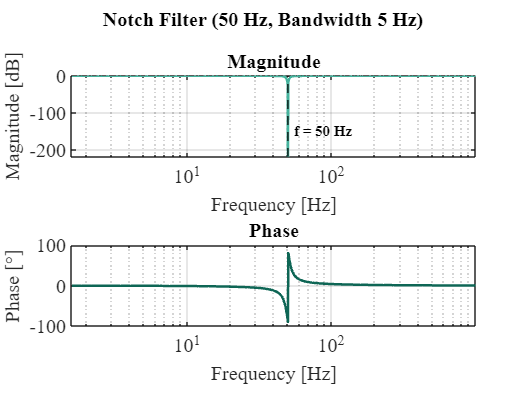


% Imposta la dimensione del font
fontSize = 16;  % Puoi modificare questo valore secondo le tue necessità
labelFontSize = fontSize - 4; % Dimensione del font per le etichette delle frequenze

% Frequenza centrale del notch e larghezza di banda
notchFreq = 50;  % Frequenza del notch
bandwidth = 5;   % Larghezza di banda

% Primo subplot: Magnitudo
subplot(2,1,1);
semilogx(freq_Hz_Notch, squeeze(20*log10(mag_Notch)), 'Color', PS.DGreen1, 'LineWidth', 2); % Magnitudo in dB
title('Magnitude', 'FontSize', fontSize);
xlabel('Frequency [Hz]', 'FontSize', fontSize+2);
ylabel('Magnitude [dB]', 'FontSize', fontSize+2);
xlim([min(freq_Hz_Notch) max(freq_Hz_Notch)]);
grid on;

% Aggiungi linee verticali tratteggiate per la frequenza di notch
hold on;
xline(notchFreq, '--k', 'LineWidth', 1.5);  % Linea tratteggiata per 50 Hz

% Aggiungi etichette per la frequenza di notch
hNotchLabel = text(notchFreq * 1.1, -150, 'f = 50 Hz', 'FontSize', labelFontSize,...
    'Color', 'k', 'FontWeight', 'bold');
hold off;

% Secondo subplot: Fase
subplot(2,1,2);
semilogx(freq_Hz_Notch, squeeze(phase_Notch), 'Color', PS.DGreen4, 'LineWidth', 2); % Fase in gradi
title('Phase', 'FontSize', fontSize);
xlabel('Frequency [Hz]', 'FontSize', fontSize+2);
ylabel('Phase [°]', 'FontSize', fontSize+2);
xlim([min(freq_Hz_Notch) max(freq_Hz_Notch)]);
grid on;

% Titolo generale in grassetto
sgtitle('Notch Filter (50 Hz, Bandwidth 5 Hz)', 'FontSize', fontSize + 2, 'FontWeight', 'bold');

% Imposta Times New Roman per tutti gli elementi del plot
set(findall(gcf, '-property', 'FontName'), 'FontName', 'Times New Roman');

% Imposta la dimensione del font per tutti gli elementi del plot (esclusi i label)
set(findall(gcf, '-property', 'FontSize'), 'FontSize', fontSize);

% Imposta la dimensione del font dell'etichetta del notch
set(hNotchLabel, 'FontSize', labelFontSize); % Imposta la dimensione del font per la label del notch

% Salva il grafico come file SVG
print(gcf, 'Notch_Filter.svg', '-dsvg', '-r600');  % Salva il grafico con il nome specificato come SVG

## **Signal Processing: Butterworth and Notch filter**

Power line interference can affect signal recording. 

Cometa sensors are not shielded against interference. Its signal was thus **filtered to avoid European power line interference (50 Hz and harmonics) **using a Hampel filter [[13](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5638457/#pone.0186132.ref013)]. (https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5638457/)

% Filters' parameters
low_cutoff = 20; 
high_cutoff = 500; 

notch_freq = 50;  % Disturbance freq (ex. 50 Hz powerline interference)
notch_bandwidth = 5;  % Bandwidth of Notch filter (5 Hz)

% BP Butterworth filter
[b_BP, a_BP] = butter(6, [low_cutoff, high_cutoff] / (fs / 2), 'bandpass');
% [b_LP, a_LP] = butter(6, high_cutoff / (fs / 2),
% 'low');

% Notch filter
[d_Notch, c_Notch] = iirnotch(notch_freq / (fs / 2), notch_bandwidth / (fs / 2));

figure;

for c = 1:length(conditions)
    condition = conditions{c};
    conditionEng = conditionsEng{c};

    for a = 1:length(angles)
        angle = angles(a);

        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;        

        figure('Name', sprintf('%s - %d°', conditionEng, angle), 'NumberTitle', 'off');
        set(gcf, 'Position', [100, 100, 1600, 900]);

        % Inizializza gli handle della legenda
        legendHandles = gobjects(2, 1); % Solo due curve (Raw e Filtered)
        
        for m = 1:numMuscles
            subplot(4, 4, m);
            hold on;

            raw_signal = emgData{:, m};

            filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
            filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);

            % Plot del segnale Raw
            h_raw = plot(time, raw_signal, 'Color', "#7E2F8E");

            % Plot del segnale filtrato
            h_filtered = plot(time, filtered_signal, "Color", "#77AC30");

            % Salva gli handle una sola volta (nel primo subplot)
            if m == 1
                legendHandles(1) = h_raw;
                legendHandles(2) = h_filtered;
            end
            
            title(nameMuscles{m}, 'Interpreter', 'none');
            xlabel('Time [s]');
            ylabel('Amplitude [\muV]');
            grid on;

            xticks(0:5:time(end));
            hold off;
        end

        % Aggiungi il titolo principale alla figura
        sgtitle(sprintf('S1 %s - H. Abd. %d°', conditionEng, angle));
        
        % Posiziona la legenda sotto il titolo principale (sgtitle)
        % Usa 'north' per posizionarla sotto sgtitle
        legend(legendHandles, {'Raw', 'Filtered'}, 'Location', 'north', 'Orientation', 'horizontal');
    end
end

% Define parameters
window_size_ms = 300;  % Window size in milliseconds

% Convert window size to samples for RMS envelope
window_size_samples = round(window_size_ms * fs / 1000);

figure;

for c = 1:length(conditions)
    condition = conditions{c};
    conditionEng = conditionsEng{c};
    
    for a = 1:length(angles)
        angle = angles(a);
        
        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;        
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;        
        
        figure('Name', sprintf('%s - %d°', condition, angle), 'NumberTitle', 'off');
        
        for m = 1:numMuscles

                % Raw EMG signal
                raw_signal = emgData{:, m};
                
                % PB Butterworth filter        
                filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
                % filtered_signal = filtfilt(b_LP, a_LP, raw_signal);
        
                % Notch filter
                filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
                
                % Full wave rectification
                rec_signal = abs(filtered_signal);
                
                %% RMS envelope
                % Step 1: Square the EMG signal
                squared_signal = rec_signal.^2;
                
                % Step 2: Apply the moving ave
                % rage on the squared signal
                rms_moving_avg = movmean(squared_signal, window_size_samples);
                
                % Step 3: Take the square root to get the RMS envelope
                rms_envelope = sqrt(rms_moving_avg);
        
                % Normalizatio to MVC
                signal_norm = rms_envelope/mvc(m);
                        
                subplot(4,4,m)

                % Plot RMS envelope normlized to MVC
                plot(time, signal_norm, 'Color', "#A2142F"); 
                set(gcf, 'Position', [100, 100, 1600, 900]); 
                
                title(nameMuscles{m}, 'Interpreter', 'none');
                xlabel('Time [s]');
                ylabel('Amplitude []');
                grid on;

                xticks(0:5:time(end));
        end
        
        % Add a main title for the entire figure
        sgtitle(sprintf('S1 %s - H. Abd. %d° - Normalization to MVC', conditionEng, angle));
    end
end

- FFT to find cutoff frequencies

- 6th order BP Butterworth filter

- Full wave rectification

- RMS envelope (Moving average with RMS via movemean function) and window size 50 ms

- Normalisation to MVC (maximu possible activation of a muscle, contract as hard as possible): comparison across difefrent subject. Act as a baseline: sEMG = RMS_envelope/MVC * 100 (represented as a percentage)

## Full wave rectification

Signal is both positive and negative, hence calculating the average power it results in 0 which is statistically insignificant.

This is because poritive and negative conribution will cancel each other when calculating an average.

Hence, the signal has to be rectified by taking the absolute value of the signal, having just teh positive components.

## **Comparison between Low Assistance, Resistance and Transparency**

% Definisci le condizioni specifiche
specificConditions = {'AssBassa', 'ResAlta', 'Eval'};
specificConditionsEng = {'Low Assistance', 'High Resistance', 'Transparency'};

% Definisci la finestra di smoothing (es. 2000 samples, puoi modificare)
smoothing_window_size = 2000;

% Iterate through each angle
for a = 1:length(angles)
    angle = angles(a);
    
    % Create a new figure for each angle
    figure('Name', sprintf('Comparison - %d°', angle), 'NumberTitle', 'off');
    set(gcf, 'Position', [100, 100, 1600, 900]);
    
    legendHandles = gobjects(1, length(specificConditions)); % Prealloca array di handle

    % Iterate through each muscle to create a subplot
    for m = 1:numMuscles
        subplot(4, 4, m);
        hold on; % Hold the plot to overlay signals from different conditions
        
        % Iterate through each specific condition
        for c = 1:length(specificConditions)
            condition = specificConditions{c};
            
            % Access the raw EMG data for this condition and angle
            emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
            time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
            
            % Segnale EMG grezzo
            raw_signal = emgData{:, m};
            
            % Filtraggio del segnale con passa banda Butterworth
            filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
    
            % Applicazione del filtro notch
            filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
            
            % Full wave rectification
            rec_signal = abs(filtered_signal);
            
            % RMS envelope
            squared_signal = raw_signal.^2;
            rms_moving_avg = movmean(squared_signal, window_size_samples);
            rms_envelope = sqrt(rms_moving_avg);
    
            % Normalization to MVC
            signal_norm = rms_envelope / mvc(m);

            % Applica moving average per rendere il segnale più smooth
            signal_smooth = movmean(signal_norm, smoothing_window_size);

            % Applica shift specifico in base all'angolo e alla condizione
            if angle == 30 && (strcmp(condition, 'ResAlta') || strcmp(condition, 'Eval'))
                shifted_time = time - 2; % Shift di -2 secondi per High Resistance e Transparency
            elseif angle == 60 && strcmp(condition, 'Eval')
                shifted_time = time - 6.5;
            elseif angle == 60 && strcmp(condition, 'ResAlta')
                shifted_time = time - 2;
            elseif angle == 60 && strcmp(condition, 'AssBassa')
                shifted_time = time - 2;
            elseif angle == 90 && strcmp(condition, 'Eval')
                shifted_time = time - 2; % Shift di -1.5 secondi per Transparency
            elseif angle == 90 && strcmp(condition, 'AssBassa')
                shifted_time = time - 4; % Shift di -4 secondi per Low Assistance
            else
                shifted_time = time; % Nessuno shift per altre condizioni e angoli
            end

             % Filtra i valori del tempo e del segnale per includere solo quelli >= 0
            valid_indices = (shifted_time >= 0) & (shifted_time <= 45);
            shifted_time = shifted_time(valid_indices);
            signal_smooth = signal_smooth(valid_indices);

            % Plot del segnale smooth normalizzato a MVC
            h = plot(shifted_time, signal_smooth, 'DisplayName', specificConditionsEng{c});
            
            % Salva l'handle solo una volta (ad es., al primo muscolo)
            if m == 1
                legendHandles(c) = h; % Memorizza solo una volta per evitare duplicati
            end
        end
        
        % Aggiungi linee verticali a 10, 20, 30 e 40 secondi
        xline(10, '--k', '1st', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(20, '--k', '2nd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(30, '--k', '3rd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(40, '--k', LineWidth=2);

        title(nameMuscles{m}, 'Interpreter', 'none');
        xlabel('Time [s]');
        ylabel('Norm. Amplitude []');
        grid on;

        xticks(0:5:45);
        hold off; % Rilascia il plot per il prossimo subplot
    end
    
    % Aggiungi titolo principale alla figura
    sgtitle(sprintf('S1 Comparison LA, HR, T - H. Abd. %d°', angle));
    
    % Posiziona la legenda sotto il titolo principale (sgtitle)
    legend(legendHandles, specificConditionsEng, 'Location', 'north', 'Orientation', 'horizontal', 'Position', [0.39346,0.031979,0.24867,0.020611]);
end

## **Comparison between Medium Assistance, Resistance and Transparency**

% Definisci le condizioni specifiche
specificConditions = {'AssMedia', 'ResAlta', 'Eval'};
specificConditionsEng = {'Medium Assistance', 'High Resistance', 'Transparency'};

% Definisci la finestra di smoothing (es. 2000 samples, puoi modificare)
smoothing_window_size = 2000;

% Iterate through each angle
for a = 1:length(angles)
    angle = angles(a);
    
    % Create a new figure for each angle
    figure('Name', sprintf('Comparison - %d°', angle), 'NumberTitle', 'off');
    set(gcf, 'Position', [100, 100, 1600, 900]);
    
    legendHandles = gobjects(1, length(specificConditions)); % Prealloca array di handle

    % Iterate through each muscle to create a subplot
    for m = 1:numMuscles
        subplot(4, 4, m);
        hold on; % Hold the plot to overlay signals from different conditions
        
        % Iterate through each specific condition
        for c = 1:length(specificConditions)
            condition = specificConditions{c};
            
            % Access the raw EMG data for this condition and angle
            emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
            time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
            
            % Segnale EMG grezzo
            raw_signal = emgData{:, m};
            
            % Filtraggio del segnale con passa banda Butterworth
            filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
    
            % Applicazione del filtro notch
            filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
            
            % Full wave rectification
            rec_signal = abs(filtered_signal);
            
            % RMS envelope
            squared_signal = raw_signal.^2;
            rms_moving_avg = movmean(squared_signal, window_size_samples);
            rms_envelope = sqrt(rms_moving_avg);
    
            % Normalization to MVC
            signal_norm = rms_envelope / mvc(m);

            % Applica moving average per rendere il segnale più smooth
            signal_smooth = movmean(signal_norm, smoothing_window_size);

            % Applica shift specifico in base all'angolo e alla condizione
            if angle == 30 && strcmp(condition, 'ResAlta')
                shifted_time = time - 1.8;
            elseif angle == 30 && strcmp(condition, 'AssMedia')
                shifted_time = time - 2;
            elseif angle == 30 && strcmp(condition, 'Eval')
                shifted_time = time - 2.5;
            elseif angle == 60 && strcmp(condition, 'ResAlta')
                shifted_time = time - 2.5;
            elseif angle == 90 && strcmp(condition, 'Eval')
                shifted_time = time - 1.5;
            elseif angle == 90 && strcmp(condition, 'AssMedia')
                shifted_time = time - 1;
            elseif angle == 60 && strcmp(condition, 'AssMedia')
                shifted_time = time - 2;
            elseif angle == 60 && strcmp(condition, 'Eval')
                shifted_time = time - 7;
            else
                shifted_time = time; % Nessuno shift per altre condizioni e angoli
            end

            % Filtra i valori del tempo e del segnale per includere solo quelli >= 0
            valid_indices = (shifted_time >= 0) & (shifted_time <= 45);
            shifted_time = shifted_time(valid_indices);
            signal_smooth = signal_smooth(valid_indices);

            % Plot del segnale smooth normalizzato a MVC
            h = plot(shifted_time, signal_smooth, 'DisplayName', specificConditionsEng{c});
            
            % Salva l'handle solo una volta (ad es., al primo muscolo)
            if m == 1
                legendHandles(c) = h; % Memorizza solo una volta per evitare duplicati
            end
        end
        
        % Aggiungi linee verticali a 10, 20, 30 e 40 secondi
        xline(10, '--k', '1st', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(20, '--k', '2nd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(30, '--k', '3rd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(40, '--k', LineWidth=2);

        title(nameMuscles{m}, 'Interpreter', 'none');
        xlabel('Time [s]');
        ylabel('Norm. Amplitude []');
        grid on;

        xticks(0:5:45);
        hold off; % Rilascia il plot per il prossimo subplot
    end
    
    % Aggiungi titolo principale alla figura
    sgtitle(sprintf('S1 Comparison MA, HR, T - H. Abd. %d°', angle));
    
    % Posiziona la legenda sotto il titolo principale (sgtitle)
    legend(legendHandles, specificConditionsEng, 'Location', 'north', 'Orientation', 'horizontal', 'Position', [0.39346,0.031979,0.24867,0.020611]);
end

**Comaprison between resistances**

% Definisci le condizioni specifiche per il confronto
specificConditions = {'ResAlta', 'ResMedia', 'ResBassa'};
specificConditionsEng = {'High Resistance', 'Medium Resistance', 'Low Resistance'};

% Definisci la finestra di smoothing (es. 2000 samples, puoi modificare)
smoothing_window_size = 2000;

% Iterate through each angle
for a = 1:length(angles)
    angle = angles(a);
    
    % Create a new figure for each angle
    figure('Name', sprintf('Comparison Resistance Levels - %d°', angle), 'NumberTitle', 'off');
    set(gcf, 'Position', [100, 100, 1600, 900]);
    
    legendHandles = gobjects(1, length(specificConditions)); % Prealloca array di handle

    % Iterate through each muscle to create a subplot
    for m = 1:numMuscles
        subplot(4, 4, m);
        hold on; % Hold the plot to overlay signals from different conditions
        
        % Iterate through each specific condition
        for c = 1:length(specificConditions)
            condition = specificConditions{c};
            
            % Access the raw EMG data for this condition and angle
            emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
            time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
            
            % Segnale EMG grezzo
            raw_signal = emgData{:, m};
            
            % Filtraggio del segnale con passa banda Butterworth
            filtered_signal = filtfilt(b_BP, a_BP, raw_signal);

            % Applicazione del filtro notch
            filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
            
            % Full wave rectification
            rec_signal = abs(filtered_signal);
            
            % RMS envelope
            squared_signal = raw_signal.^2;
            rms_moving_avg = movmean(squared_signal, window_size_samples);
            rms_envelope = sqrt(rms_moving_avg);

            % Normalization to MVC
            signal_norm = rms_envelope / mvc(m);

             % Applica moving average per rendere il segnale più smooth
            signal_smooth = movmean(signal_norm, smoothing_window_size);

            % Applica shift specifico in base all'angolo e alla condizione
            if angle == 30 && strcmp(condition, 'ResBassa') 
                shifted_time = time - 5; 
            elseif angle == 30 && strcmp(condition, 'ResMedia')
                shifted_time = time - 8; 
            elseif angle == 30 && strcmp(condition, 'ResAlta')
                shifted_time = time - 1.5;
            elseif angle == 60 && (strcmp(condition, 'ResMedia') || strcmp(condition, 'ResAlta'))
                shifted_time = time - 2;
            elseif angle == 60 && strcmp(condition, 'ResBassa')
                shifted_time = time - 1;
            elseif angle == 90 && strcmp(condition, 'ResBassa')
                shifted_time = time - 2.5;
            else
                shifted_time = time; % Nessuno shift per altre condizioni e angoli
            end

            % Filtra i valori del tempo e del segnale per includere solo quelli >= 0
            valid_indices = (shifted_time >= 0) & (shifted_time <= 45);
            shifted_time = shifted_time(valid_indices);
            signal_smooth = signal_smooth(valid_indices);

            % Plot del segnale smooth normalizzato a MVC
            h = plot(shifted_time, signal_smooth, 'DisplayName', specificConditionsEng{c});
            
            % Salva l'handle solo una volta (ad es., al primo muscolo)
            if m == 1
                legendHandles(c) = h; % Memorizza solo una volta per evitare duplicati
            end
        end
        
        % Aggiungi linee verticali a 10, 20, 30 e 40 secondi
        xline(10, '--k', '1st', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(20, '--k', '2nd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(30, '--k', '3rd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(40, '--k', LineWidth=2);

        title(nameMuscles{m}, 'Interpreter', 'none');
        xlabel('Time [s]');
        ylabel('Norm. Amplitude []');
        grid on;

        xticks(0:5:45);
        hold off; % Rilascia il plot per il prossimo subplot
    end
    
    % Aggiungi titolo principale alla figura
    sgtitle(sprintf('S1 Resistance Levels Comparison - H. Abd. %d°', angle));
    
    % Posiziona la legenda sotto il titolo principale (sgtitle)
    legend(legendHandles, specificConditionsEng, 'Location', 'north', 'Orientation', 'horizontal', 'Position', [0.39346,0.031979,0.24867,0.020611]);
end

## **Comparison between Assistances**

% Definisci le condizioni specifiche
specificConditions = {'AssBassa', 'AssMedia'};
specificConditionsEng = {'Low Assistance', 'Medium Assistance'};

% Definisci la finestra di smoothing (es. 2000 samples, puoi modificare)
smoothing_window_size = 2000;

% Iterate through each angle
for a = 1:length(angles)
    angle = angles(a);
    
    % Create a new figure for each angle
    figure('Name', sprintf('Comparison - %d°', angle), 'NumberTitle', 'off');
    set(gcf, 'Position', [100, 100, 1600, 900]);
    
    legendHandles = gobjects(1, length(specificConditions)); % Prealloca array di handle

    % Iterate through each muscle to create a subplot
    for m = 1:numMuscles
        subplot(4, 4, m);
        hold on; % Hold the plot to overlay signals from different conditions
        
        % Iterate through each specific condition
        for c = 1:length(specificConditions)
            condition = specificConditions{c};
            
            % Access the raw EMG data for this condition and angle
            emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
            time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
            
            % Segnale EMG grezzo
            raw_signal = emgData{:, m};
            
            % Filtraggio del segnale con passa banda Butterworth
            filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
    
            % Applicazione del filtro notch
            filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
            
            % Full wave rectification
            rec_signal = abs(filtered_signal);
            
            % RMS envelope
            squared_signal = raw_signal.^2;
            rms_moving_avg = movmean(squared_signal, window_size_samples);
            rms_envelope = sqrt(rms_moving_avg);
    
            % Normalization to MVC
            signal_norm = rms_envelope / mvc(m);

            % Applica moving average per rendere il segnale più smooth
            signal_smooth = movmean(signal_norm, smoothing_window_size);

            % Applica shift specifico in base all'angolo e alla condizione
            if angle == 60 && strcmp(condition, 'AssBassa')
                shifted_time = time - 2.7;
            elseif angle == 60 && strcmp(condition, 'AssMedia')
                shifted_time = time - 2.5;
            elseif angle == 90 && strcmp(condition, 'AssMedia')
                shifted_time = time - 1.5;
            elseif angle == 90 && strcmp(condition, 'AssBassa')
                shifted_time = time - 4;
            else
                shifted_time = time; % Nessuno shift per altre condizioni e angoli
            end
            
             % Filtra i valori del tempo e del segnale per includere solo quelli >= 0
            valid_indices = (shifted_time >= 0) & (shifted_time <= 45);
            shifted_time = shifted_time(valid_indices);
            signal_smooth = signal_smooth(valid_indices);

            % Plot del segnale smooth normalizzato a MVC
            h = plot(shifted_time, signal_smooth, 'DisplayName', specificConditionsEng{c});
            
            % Salva l'handle solo una volta (ad es., al primo muscolo)
            if m == 1
                legendHandles(c) = h; % Memorizza solo una volta per evitare duplicati
            end
        end
        
        % Aggiungi linee verticali a 10, 20, 30 e 40 secondi
        xline(10, '--k', '1st', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(20, '--k', '2nd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(30, '--k', '3rd', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'middle', LineWidth=2);
        xline(40, '--k', LineWidth=2);

        title(nameMuscles{m}, 'Interpreter', 'none');
        xlabel('Time [s]');
        ylabel('Norm. Amplitude []');
        grid on;

        xticks(0:5:45);
        hold off; % Rilascia il plot per il prossimo subplot
    end
    
    % Aggiungi titolo principale alla figura
    sgtitle(sprintf('S1 Assistance Levels Comparison - H. Abd. %d°', angle));
    
    % Posiziona la legenda sotto il titolo principale (sgtitle)
    legend(legendHandles, specificConditionsEng, 'Location', 'north', 'Orientation', 'horizontal', 'Position', [0.39346,0.031979,0.24867,0.020611]);
end

## PSD (Power Spectral Density) and Fatigue

The PSD is an estimation of a signal's power distribution over frequency.

The physiological importance of performing a frequency domain analysis of an EMG signal lies in the possibility of detecting and monitoring muscle fatigue throughout the motion. 

The relevant information is contained in the raw, unfiltered signal. As a consequence of muscle fatigue, the PSD spectrum of the signal is progressively compressed towards the lower frequencies,and its amplitude increases.

The PSD is computed using **Welch Periodogram**: the signal is split into multiple bins and the power spectral density is computed in each of them. 

The Pwelch algorithm is **applied to the signal after removing its mean value** to avoid distortions in the low frequencies (due to truncation of the signal) when convoluting the signal with the sync. 

The size of the bins was selected in order to have an acceptable number of bins (depending on the length of the whole signal) to properly evaluate fatigue: four bins were obtained.

In the graphs below, the PSDs of the first and last bin are shown together to underline their differences.

Whereas **fatigue** is calculated as a **weighted average of the frequencies of the signal** with the power values as weights.

It is visible how the fatigue (PSD) graphs tend to decreas with time, and this is coherent with the previous statement, since the signals have progressively lower frequencies.

% Parameters for smoother PSD calculation
ns = 1024; % Larger segment length
noverlap = ns * 0.75; % Overlap should be less than segment length (50% overlap)
nt = ns * 64; % Larger bin size (samples) for averaging PSD

% Cycle for all the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    
    % Cycle for all the abduction angles
    for a = 1:length(angles)
        angle = angles(a);
        
        % Access EMG data
        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
        
        % Convert the table to array
        emgDataArray = table2array(emgData);
        
        % Create a new figure for each condition and angle
        figure('Name', sprintf('PSD: %s - %d°', condition, angle), 'NumberTitle', 'off');
        
        for m = 1:numMuscles
            % Select the EMG data for the current muscle
            muscleData = emgDataArray(:, m);
            
            % Check if muscleData is long enough for analysis
            if length(muscleData) < nt
                warning('Segnale troppo corto per il calcolo di PSD con finestra di %d campioni.', nt);
                continue; % Skip this muscle and go to the next one
            end
            
            % Detrend the data (remove mean)
            muscleData = muscleData - mean(muscleData);
            
            % Define the first and last windows
            firstWindow = 1:nt; % First window of data
            lastWindow = (length(muscleData) - nt + 1):length(muscleData); % Last window of data
            
            % Calculate PSD for the first window with 50% overlap
            [PxxFirst, f] = pwelch(muscleData(firstWindow), hamming(ns), noverlap, ns, fs);
            
            % Calculate PSD for the last window with 50% overlap
            [PxxLast, f] = pwelch(muscleData(lastWindow), hamming(ns), noverlap, ns, fs);
            
            % Plot the PSD for the current muscle
            subplot(4, 4, m);
            plot(f, 10*log10(PxxFirst)); % Plot in black for early window
            hold on;
            plot(f, 10*log10(PxxLast), 'r'); % Plot in red for late window
            title(nameMuscles{m}, 'Interpreter', 'none');
            xlabel('Frequency [Hz]');
            ylabel('PSD [dB/Hz]');
            xlim([0 350]); % Limit the frequency range
            grid on;

            legend({'Early', 'Late'}, 'Location', 'best');
       
        end
        
        % Add a title for the entire figure
        sgtitle(sprintf('PSD per Condizione: %s, Angolo: %d°', condition, angle));
        
        % Adjust the figure size
        set(gcf, 'Position', [100, 100, 1200, 900]);
    end
end